# Modelling Stochastic Chemical Kinetics

## Introduction

The kinetics of a well-mixed chemical composition can  be modelled using stochastic differential equations due to the inherent randomness of the collision of the molucules. If the systems has sufficiently many particles, or in statistical mechanics terminolgy, approaches the thermodynamic limit of infinite molecular populations, the Langevin and Fokker-Planck stochastic differential equations can be used. However, the chemical master equation (CME) is more sultable if the system is composed of small molecular population levels, as is the case in cellular biological systems and biochemical processes such as DNA transcription regulation, translation and protein phosphorylation. In this notebook, we explore methods of solution to the CME, the chemical Fokker-Planck equation (CFPE), and the chemical Langevin equation (CLE). The stochastic Schlogl model is given by a CME with infinitely coupled ordinary differential equations, which can be truncated at some finite number, N, for numerical purposes. In this project, we demonstrate the numerical modelling a Schlogl model as a discrete CME. 

## The Schlogl Model

The Schlogl model, named after its author F. Schlogl, is a chemical reaction network, which in its stochastic form, exhibits bistability. The model was first developed to understand non-equilibrium phase transitions in well-stirred chemical reactions by analyzing the steady states and unstable states with respect to the concentrations of the reacting species. Typically, the concentrations of some of the species is kept constant while the concentration(s) of other species is allowed to change. These species with the variable cencentration are refered to as the dynamic species. The Schlogl model can be deterministic or stochastic depending on the whether the concentration of the dynamic species is allowed to flacuate randomly or in a predictable way. The stochastic Schlogl model is given in the form of a CME as an infinte sum of coupled ordinary differential equations. From the orginal paper Vellela paper, the constants used are as follows: a=1; b=1; k1=3; k2=0.6; k3=0.25; k4=2.95.

% intialization
clear; clc;

% model parameters
a = 1;
b = 1;
k1 = 3;
k2 = 0.54;
k3 = 0.25;
k4 = 2.95;

% computations for variable volume
N = 1000;
Vn = 10:10:100;
lambda0 = zeros(length(Vn),1);
lambda1 = zeros(length(Vn),1);
v0 = zeros(N,length(Vn));
v1 = zeros(N,length(Vn));
i=1;
%******************************************
for V = Vn
    
% birth and death rates
lambda = @(n) ((a*k1*n*(n-1))/V + b*k3*V);
mu = @(n) ((k2*n*(n-1)*(n-2))/V^2 + n*k4);

% stochastic matrix Q of dimension NxN
Q = TridiagA(lambda,mu,N);

% % is hermitian?
% ishermitian(Q)

% computing the eigenvalues and eigenvectors
[v,d] = eigs(Q,2,'smallestabs');
d = diag(d);
lambda0(i) = min(abs(d));
lambda1(i) = max(abs(d));
v0(:,i) = v(:,1);
v1(:,i) = v(:,2);

i=i+1;

end

## Plotting the Steady State and Eigenvalues $\lambda_0$ and $\lambda_1$

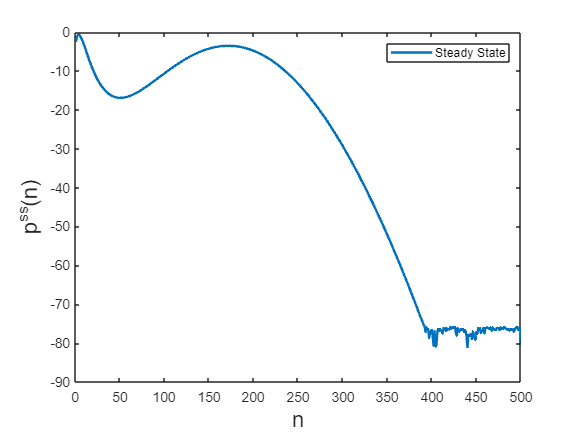

% plotting for a selected volume, say, V = q*10:
q = 4;

% plotting steady state
% this is the eigenvector that corresponds
% to the eigenvalue: lambda = 0.
vec = real(log(v0(:,q)));
vec_round = round(vec);
plot(vec,"-","DisplayName","Steady State",LineWidth=1.8)
xlim([0 500])
xlabel("n","FontSize",16)
ylabel("p^{ss}(n)","FontSize",16)
legend("Location","northeast")

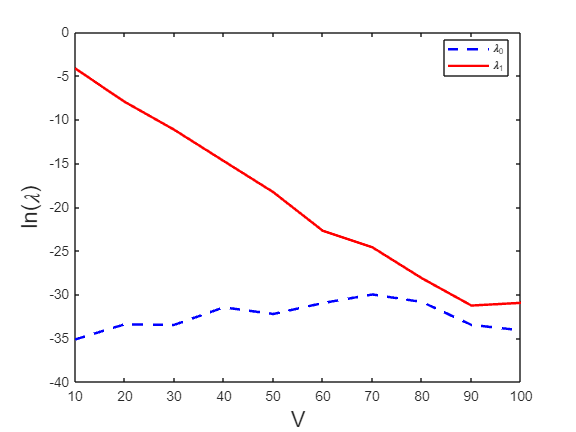


% plotting eigenvalues for varying V
plot(Vn,log(lambda0),"--b","DisplayName","\lambda_0",LineWidth=1.8); hold on;
xlabel("V","FontSize",16)
ylabel("ln(\lambda)","FontSize",16)
legend("Location","best")
plot(Vn,log(lambda1),"-r","DisplayName","\lambda_1",LineWidth=1.8);
hold off;


%*************************************

## Orthogonal Subspaces

Next, we are going to see if the first eigenstate is orthogonal to the second eigenstate. 

% picking 1st and 2nd eigenvectors for a selected volume, V=q*10:
f0 = v0(:,q);
f1 = v1(:,q);

% The dot product must be 0 for orthogonal vectors
dot(f0/norm(f0), f1/norm(f1))

ans = 0.8841

dot(f0, f1)

ans = 0.8841

% angle between them
angle_rad = subspace(f0,f1)

angle_rad = 0.4863

angle_degrees = rad2deg(angle_rad)

angle_degrees = 27.8648